# MATLAB as an Engineer's Problem Solving Tool

# Name: Buddy Ugwumba SID: 862063029

## 2 Matlab Tutorial

###     2.3 Matrices and Arrays

    % A 3x1 matrix
    A = [pi; sqrt(2); exp(1)];

    %B = 3x1
    B = [1; 5; 7];

    %We must transpose A because the rules for matrix multiplication require
    %that columns of A match the rows of B. Transposing matrix makes A = 1x3
    %therefore the column of A now matches B

    C = A'*B

C = 29.2406

###     2.5 Scripts:

    A = [pi; sqrt(2); exp(1)];
    B = [1; 5; 7];
    D = 0 ;
    % c) Implement a for loop to compute the summation of matrix A times B
    % Answer should be identical to C in Exercise_1

    % i = loop index; loop index must be a row vector; starts at one ends at 3
    for i = 1:3
        D = D + A(i)'*B(i)
    end

D = 3.1416

D = 10.2127

D = 29.2406

### 2.6 More Advanced Scripts

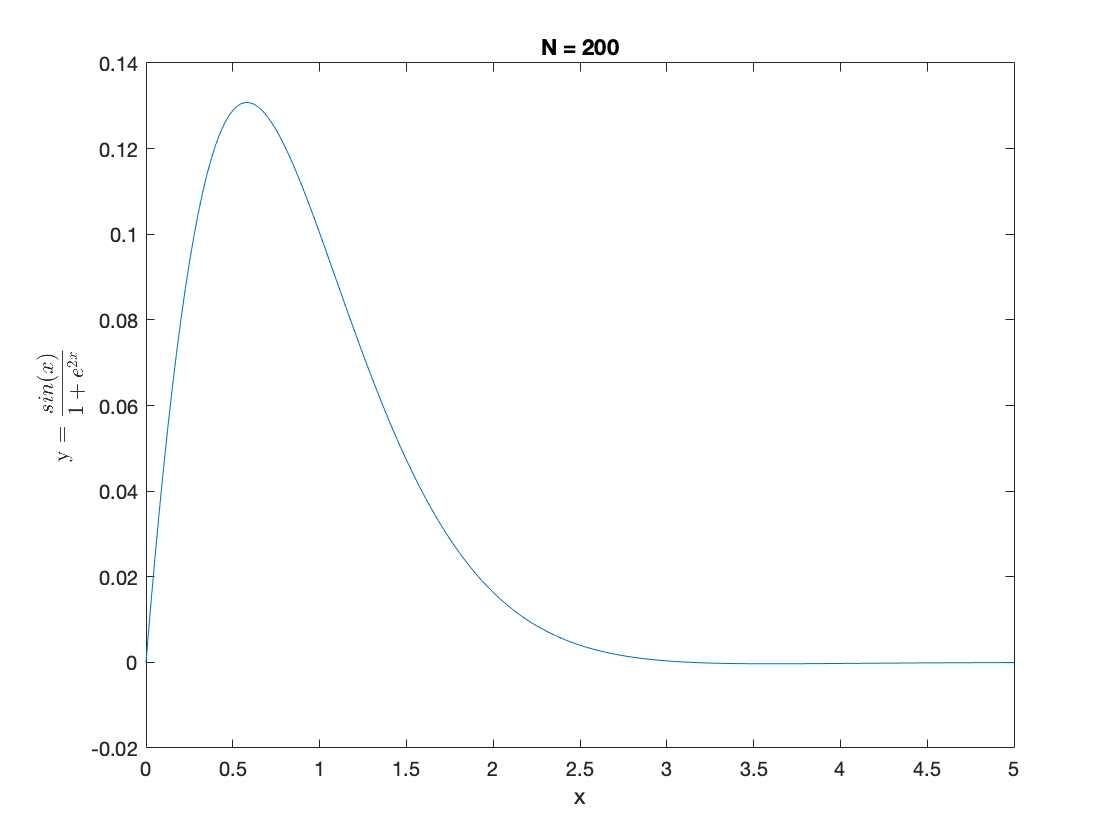

% N = 200
plottingFunc(200);

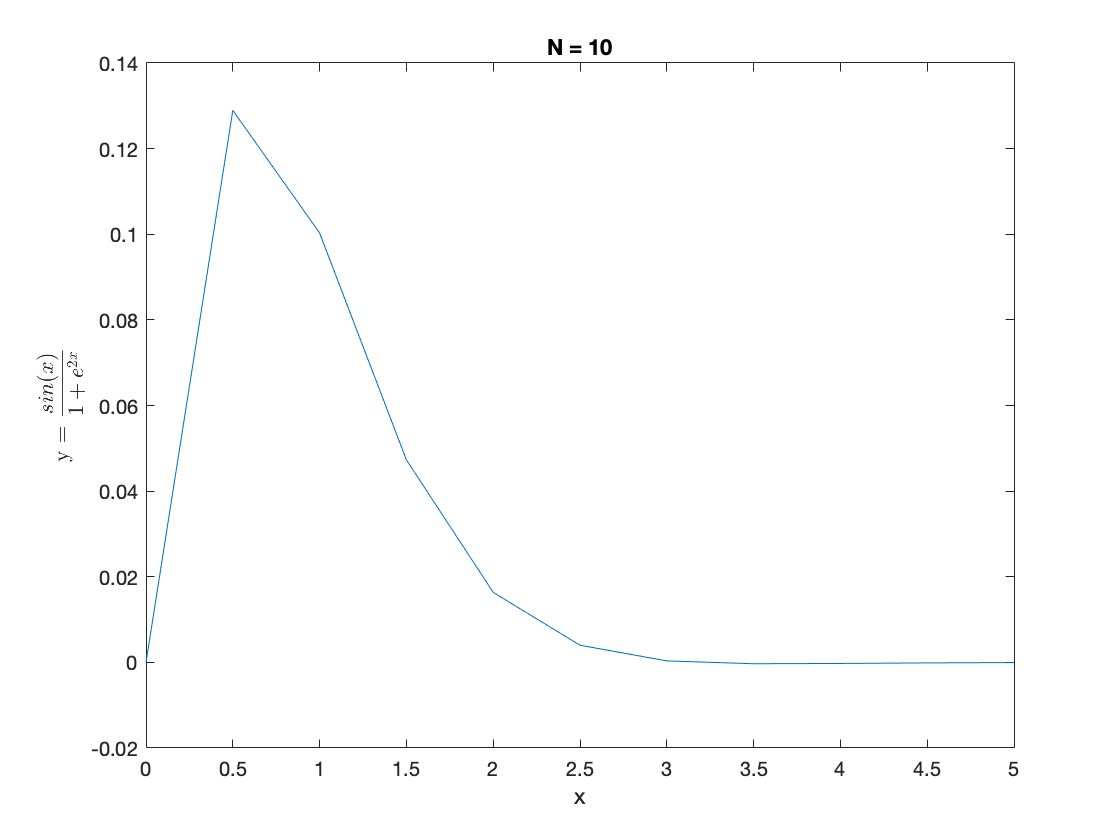

% N = 10
plottingFunc(10);

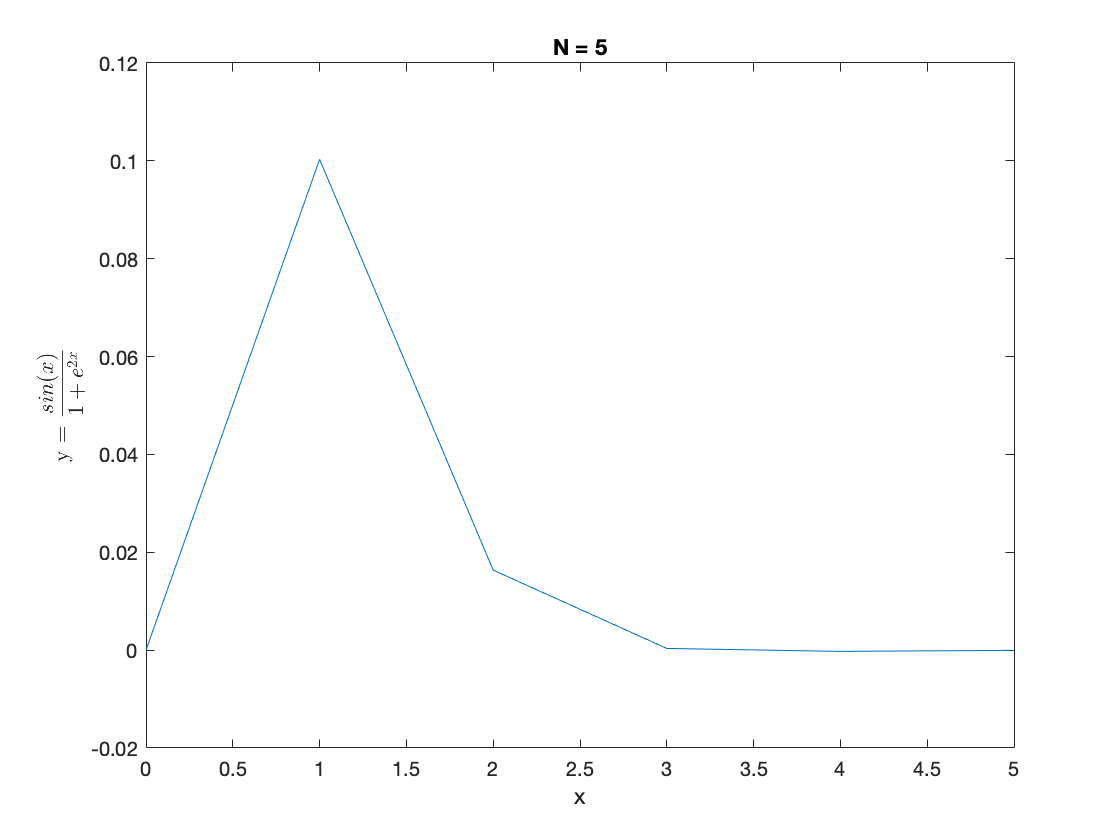

% N = 5
plottingFunc(5);

### 2.7 (b) Comparing approaches  to integration

(i & ii) The purpose of this section is to investigate the Riemannn Sum. We only need to perfom a right sided integral

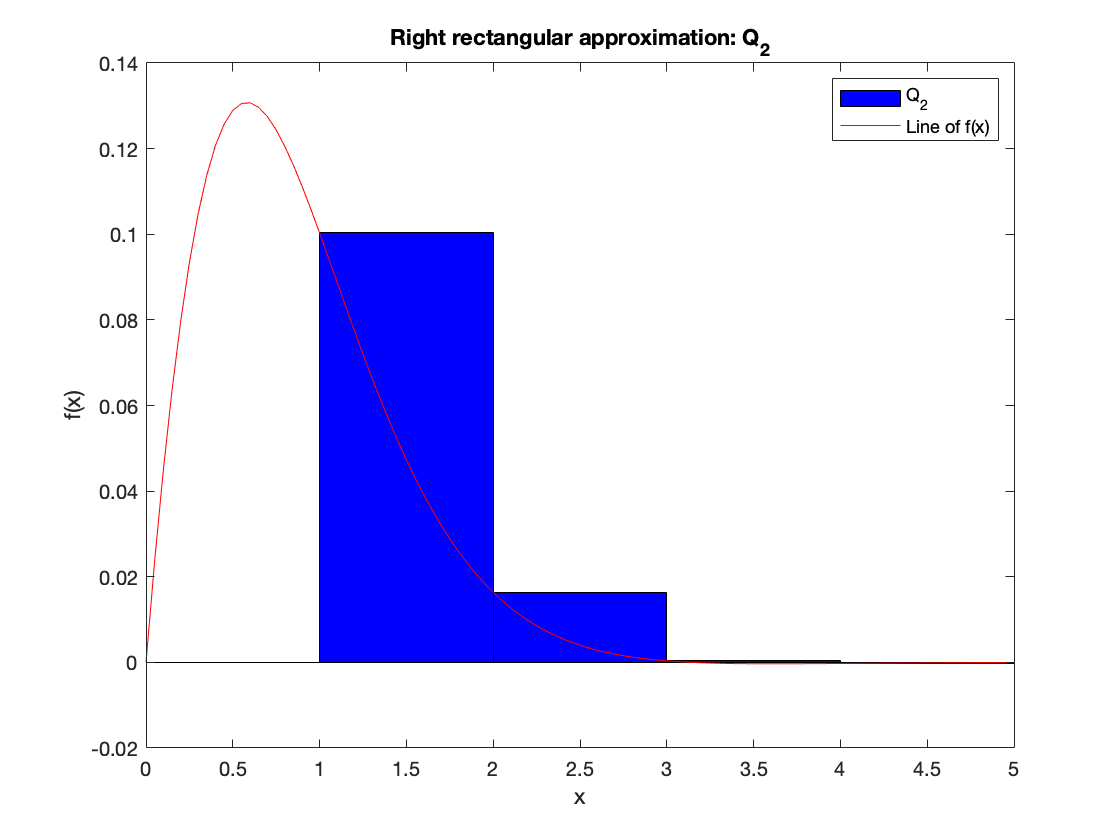

N = 5;
dx = 5/N;
x_bar = 0:dx:5;
y_bar = outputVecFunc(x_bar);
A = ones(N, 1);
Q_2 = y_bar.*A.*dx;
% Compute f(x)
x = 0:5/100:5;
y = outputVecFunc(x);
figure
% Plot the bar
% '+dx/2 moves the bar to the right side
bar(x_bar +dx/2,y_bar,1,'blue')
xlim([0,5]);
hold on % Hold the graphs in the same figure
% plot f(x)
plot(x,y,'red');
title('Right rectangular approximation: Q_2');
xlabel('x');
ylabel('f(x)');
legend('Q_2','Line of f(x)');

The explanation for the equation of Q(2) is as follows. we want the sum of infinitesimal areas of function multiplied by an infinitesimal incrementation of a change in x. This is what creates the small rectangles. Therefore the tradeoffs related to decreasing dx is increased accuracy.

### (iii)

    A) Derive this equation for $Q_3$: $f\left(x_0 \right)\left({\mathrm{dx}}_0 \right)+0\ldotp 5\left(f\left(x_1 \right)-f\left(x_0 \right)\right)\left({\mathrm{dx}}_0 \right)$

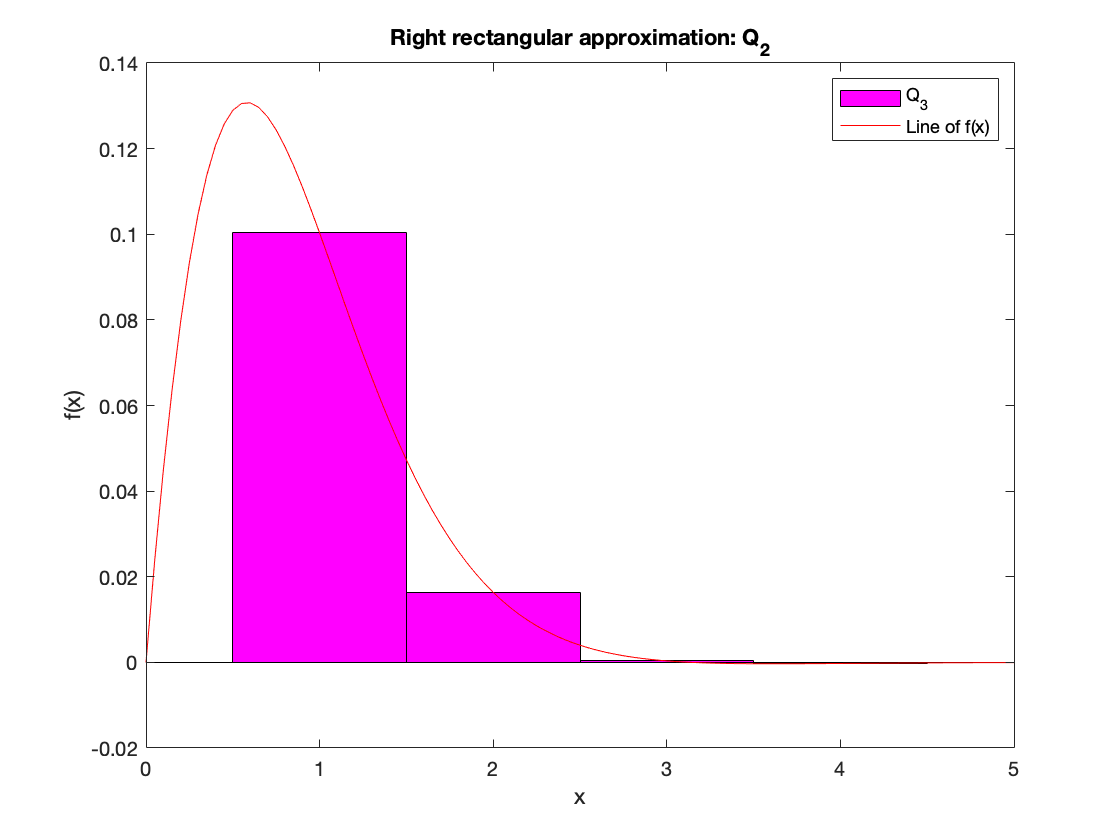

N = 5;
dx = 5/N;
x_bar = 0:dx:5;
y_bar = outputVecFunc(x_bar);
figure 
% Plot the bar
% '-dx/2 moves the bar to the right side
bar(x_bar, y_bar,1,'magenta');
xlim([0,5]);
hold on % Hold the graphs in the same figure
% plot f(x)
plot(x,y,'red');
title('Right rectangular approximation: Q_2');
xlabel('x');
ylabel('f(x)');
legend('Q_3','Line of f(x)');

### B Show that for equally spaced $x_i$ (i.e., ${\mathrm{dx}}_i ={\mathrm{dx}}_{i-1}$); $Q_3 =\frac{Q_1 +Q_2 }{2}$

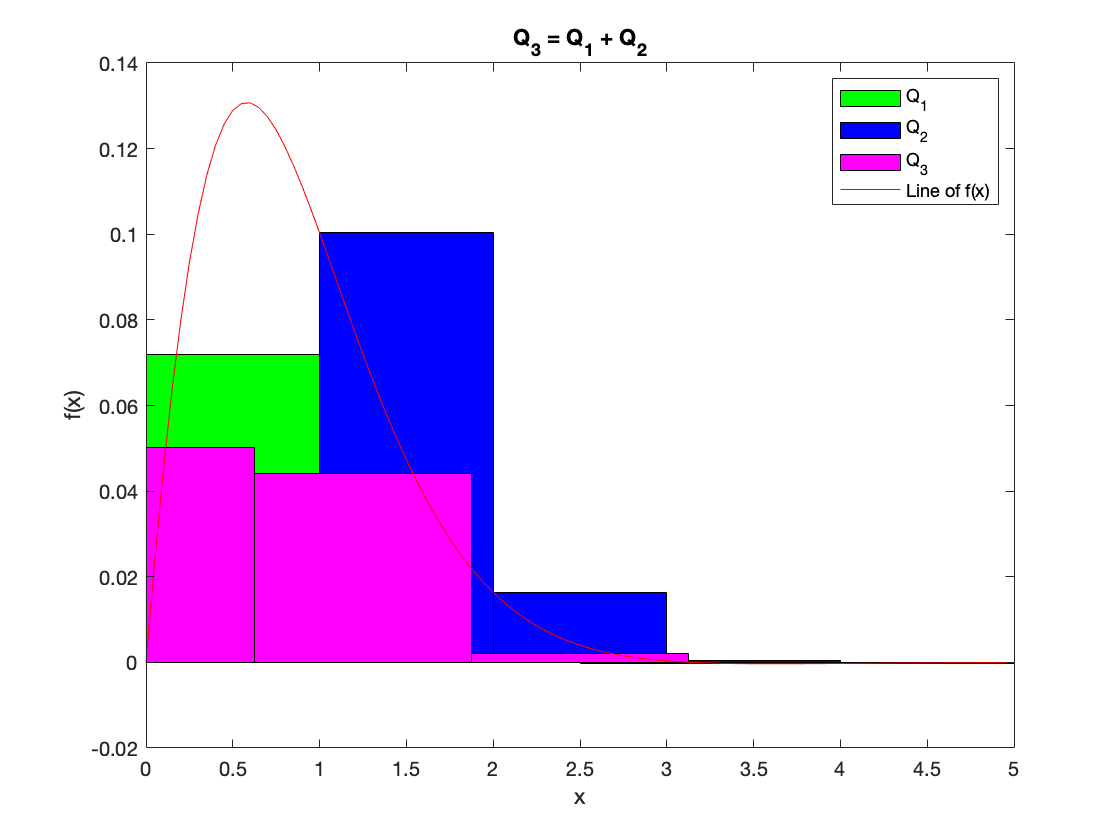

% Q_1
N = 5;
dx = 5/(N - 1);
Q_1_x_bar = 0:dx:5;
Q_1_y_bar = outputVecFunc(Q_1_x_bar);
A = ones(N-1, 1);
Q_1 = Q_1_y_bar.*A.*dx;
figure
bar(Q_1_x_bar-dx/2, Q_1_y_bar,1,'green');
xlim([0,5]);
hold on
% Q_2
N = 5;
dx = 5/N;
Q_2_x_bar = 1:dx:5;
Q_2_y_bar = outputVecFunc(Q_2_x_bar);
A = ones(N,1);
Q_2 = Q_1_y_bar.*A.*dx;
bar(Q_2_x_bar +dx/2, Q_2_y_bar, 1,'blue');
hold on
% Q_3
bar(Q_1_x_bar, (Q_1_y_bar + Q_2_y_bar)*0.5, 1, 'magenta');
hold on
plot(x, y,'red');
title('Q_3 = Q_1 + Q_2');
xlabel('x');
ylabel('f(x)');
legend('Q_1','Q_2','Q_3','Line of f(x)');

D, 

function calculation = q3(o)
calculation = (sin(o)./(1 + exp(2.*o))).*o + 0.5*((sin(o(1,2:4))/(1 + exp(2*o(1,2:4)))) - (sin(o)./(1 + exp(2.*o)))).*o;
end

function z = myfunc(n, o)
 z = sin(n)./(1 + exp(2.*n)).*o;
end

function Q3 = first_function(n)
Q3 = sin(n(1,2))/(1+exp(2*n(1,2))) + n(1,2)*(sin(n(1,3))/(1+exp(2*n(1,3))) - sin(n(1,2))/(1+exp(2*n(1,2))))*0.5;
end